# POST-PROCESSING OF IMAGES FROM PLANAR KIRIGAMI EXPERIMENTS

"Continuum Field Theory for the Deformations of Planar Kirigami" Yue Zheng, Imtiar Niloy, Paolo Celli, Ian Tobasco, and Paul Plucinsky Phys. Rev. Lett. 128, 208003 ? Published 20 May 2022

% Code created on July 2021

close all;
clear all;
clc;

## INPUT NEEDED -- CHOICE OF SPECIMEN/EXPERIMENTAL RESULT TO ANALYZE

%filename='061521_AnIsoLRSidesCenterPull_v2_7cm'; para = [3 100]; % for Hyperbolic Pulling

filename='060821_IsoLRSidesCenterPull_8cm'; para = [0 42]; % for Elliptic Pulling
filename='060821_IsoLRSidesCenterPull_0cm'; para = [0 42]; % for Elliptic Pulling

% filename = '070121_ForcedIntoAnnulus_Hyperbolic'; para = [0 42]; % for Hyperbolic Annulus

% filename = '070121_ForcedIntoAnnulus_Elliptic'; para = [0 42]; % for Elliptic Annulus

%filename = '063021_Mixed_LRSidesCenterPull_6'; para = [0 100]; %Test for mixed

## IMAGE READ

I = imread([filename,'.tif']);

BW = imbinarize(I);
BW = logical(1 - BW);

stats = regionprops('table',BW,'Centroid','Area','MajorAxisLength','MinorAxisLength','Orientation');
Cent = stats.Centroid;
Area = stats.Area;
Maax = stats.MajorAxisLength;
Miax = stats.MinorAxisLength;
Orit = stats.Orientation;
Orit = -Orit/180*pi;

hinge = para(1);
Maax = Maax + hinge;
Maax(Maax>para(2))=para(2);

Angle=atan(Miax./Maax);
%xi_in = 0.32 %0.219; %For mixed kirigami
%xi_in = 0.06; %0.06; %For hyperbolic kirigami
xi_in = 0.11; %0.09; %For auxetic kirigami
Angle = Angle-xi_in;

## INPUT NEEDED -- CHOOSE SLIT THRESHOLDS

%Slit=(Area>20 & Area<1000); % for Hyperbolic Pulling

Slit=(Area>20 & Area<3200); % for Elliptic Pulling

% Slit=(Area>20 & Area<1000); % for Hyperbolic Annulus

% Slit=(Area>20 & Area<2000); % for Elliptic Annulus

%Slit=(Area>200 & Area<1700) & Maax < 60;% for Mixed Pulling

## PLOTS

disp(Cent(Slit,1))

   1.0e+03 *

    0.0483
    0.0311
    0.0269
    0.0674
    0.0290
    0.0311
    0.0401
    0.0360
    0.0376
    0.0499
    0.0338
    0.0364
    0.0344
    0.0354
    0.0378
    0.0534
    0.0764
    0.0525
    0.0778
    0.0568
    0.0598
    0.0597
    0.0605
    0.0900
    0.0772
    0.0731
    0.0668
    0.0675
    0.0680
    0.0686
    0.0684
    0.0689
    0.0941
    0.0683
    0.0681
    0.0678
    0.0682
    0.0677
    0.0689
    0.0905
    0.0944
    0.0704
    0.0704
    0.0709
    0.0705
    0.0715
    0.0715
    0.0717
    0.0724
    0.0723
    0.0723
    0.0720
    0.0721
    0.0718
    0.0710
    0.1174
    0.0828
    0.0843
    0.0830
    0.1159
    0.0837
    0.0832
    0.0868
    0.0831
    0.0841
    0.0835
    0.0844
    0.0848
    0.1042
    0.1007
    0.1057
    0.1179
    0.1091
    0.1334
    0.1344
    0.1080
    0.1120
    0.1354
    0.1374
    0.1181
    0.1166
    0.1156
    0.1158
    0.1174
    0.1164
    0.1163
    0.1163
    0.1160
    0.1161
    0.1

disp(Cent(Slit,2))

   1.0e+03 *

    0.8081
    0.7611
    0.8559
    0.9529
    0.3825
    0.4765
    0.5713
    0.6664
    1.0491
    1.4722
    1.1440
    1.2376
    1.5200
    1.3313
    1.4249
    1.0958
    0.3817
    0.7135
    0.8563
    0.4288
    1.3780
    1.2840
    1.1900
    0.6661
    0.5712
    0.7607
    0.9040
    0.8436
    1.0012
    0.3313
    0.3947
    0.4623
    0.4763
    0.5255
    0.6179
    0.6830
    0.7439
    0.7755
    1.0630
    1.7096
    1.0478
    1.1295
    1.1553
    1.6942
    1.7494
    1.2235
    1.6027
    1.2489
    1.3204
    1.3425
    1.4118
    1.4496
    1.5041
    1.5338
    1.6470
    0.9038
    0.5236
    0.6188
    0.7133
    0.8082
    1.0001
    0.3342
    0.4292
    1.0950
    1.1893
    1.2834
    1.4722
    1.3776
    1.2367
    0.7607
    1.4252
    1.7580
    1.5192
    0.5236
    0.7132
    0.5713
    1.3307
    0.6184
    0.9989
    0.4292
    0.3824
    0.8571
    0.9511
    0.3274
    0.4453
    0.5036
    0.5711
    0.6629
    0.8003
    1.0

disp(Angle(Slit))

   -0.0387
    0.0663
    0.2890
   -0.0332
    0.2787
    0.0651
   -0.0402
   -0.0196
   -0.0229
   -0.0381
    0.0185
    0.0200
    0.0862
    0.0299
   -0.0117
   -0.0380
   -0.0461
   -0.0198
   -0.0209
    0.0095
    0.0018
    0.0083
    0.0363
   -0.0470
   -0.0662
   -0.0065
   -0.0251
    0.0282
   -0.0492
   -0.0200
    0.0075
   -0.0281
   -0.0419
   -0.0479
   -0.0516
   -0.0391
   -0.0481
   -0.0148
   -0.0162
   -0.0357
   -0.0450
   -0.0176
    0.0060
   -0.0047
   -0.0525
   -0.0068
    0.0356
    0.0082
    0.0465
    0.0027
   -0.0043
   -0.0492
   -0.0370
   -0.0076
   -0.0665
   -0.0446
   -0.0038
   -0.0282
   -0.0104
   -0.0475
   -0.0312
    0.0187
   -0.0390
   -0.0240
    0.0023
    0.0246
    0.0033
    0.0022
   -0.0242
   -0.0095
   -0.0073
   -0.0606
    0.0366
   -0.0488
   -0.0567
    0.2868
    0.1604
   -0.0477
   -0.0417
    0.0084
   -0.0346
   -0.0433
   -0.0386
    0.1798
   -0.0340
   -0.0426
   -0.0439
   -0.0497
    0.2232
   -0.0400
   -0.0825

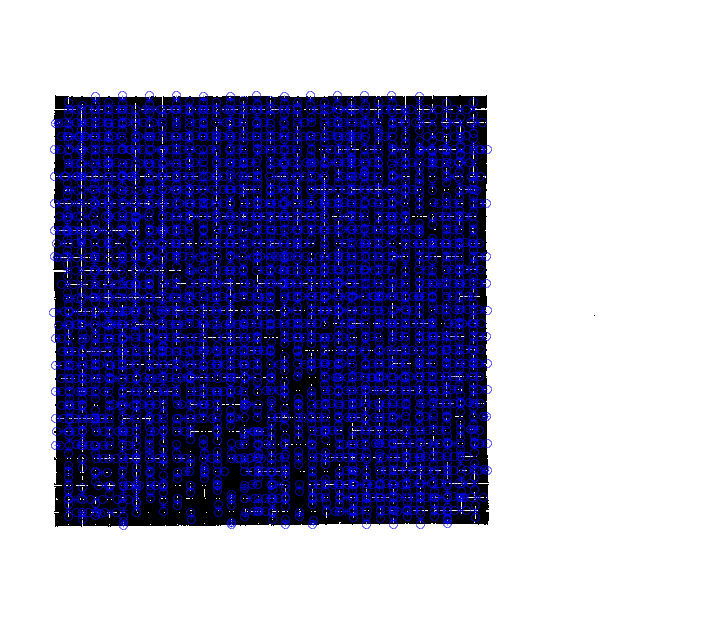


figure;
imshow(BW);
hold on;
plot(Cent(Slit,1),Cent(Slit,2),'b*')

plot([Cent(Slit,1)+Maax(Slit)/2.*cos(Orit(Slit)) Cent(Slit,1)-Maax(Slit)/2.*cos(Orit(Slit))]...
    ,[Cent(Slit,2)+Maax(Slit)/2.*sin(Orit(Slit)) Cent(Slit,2)-Maax(Slit)/2.*sin(Orit(Slit))],'bo')



figure;
subimage(BW);
hold on;
scatter2 = scatter(Cent(Slit,1),Cent(Slit,2),100,Angle(Slit),'filled')

scatter2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'none'
    MarkerFaceColor: 'flat'
          LineWidth: 0.5000
              XData: [48.3014 31.0526 26.8750 67.3731 29.0286 31.0909 40.1039 36.0182 37.5946 49.9444 33.8286 36.4000 34.3590 35.4333 37.7895 53.3800 76.4275 52.4681 77.8020 56.7805 59.8261 59.6667 60.5000 90.0375 77.1915 73.1071 66.8376 67.5000 … ]
              YData: [808.1096 761.0526 855.8750 952.9055 382.5143 476.4545 571.3117 666.4182 1.0491e+03 1.4722e+03 1.1440e+03 1.2376e+03 1.5200e+03 1.3313e+03 1.4249e+03 1.0958e+03 381.6522 713.5319 856.3119 428.7805 1.3780e+03 1.2840e+03 1190 … ]
           SizeData: 100
              CData: [1650×1 double]

  Show 

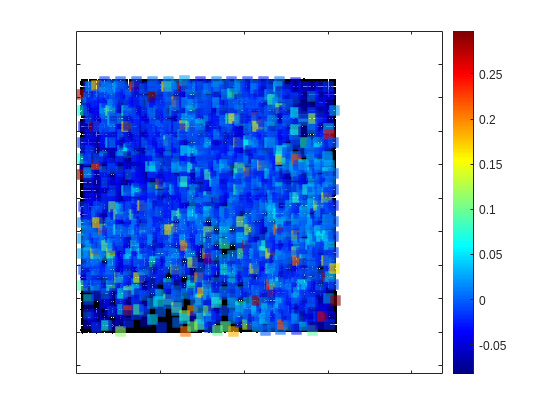

colormap jet;
scatter2.MarkerFaceAlpha = .6;
scatter2.Marker = 's';
set(gca,'XtickLabel',[],'YtickLabel',[])
colorbar